# Estimating Clients' Needs: from "Needs" dataset to "BankClients"

Our aim is to build a classifier for accumulation/income investment training in a supervised fashion on Needs dataset in order to predict the right product for the Bankclients.

#### *Load datasets*

close all
clc
path = 'Needs.mat';         % Load the dataset
load(path)
Data_Needs = Needs;         % Renaming (we'll likely manipulate this matrix, but we don't touch the original matrix)
path = 'BankClients.mat';   % Load the dataset
load(path)
Data_BankClients = BankClients;

## Quick data exploration

We start looking at univariate distributions in the dataset Data_Needs. For example, we check for unbalanced classes.

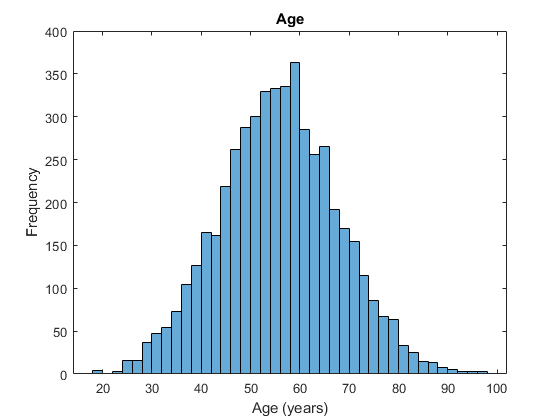

figure
histogram(Data_Needs.Age)
title('Age')
xlabel('Age (years)')
ylabel('Frequency')

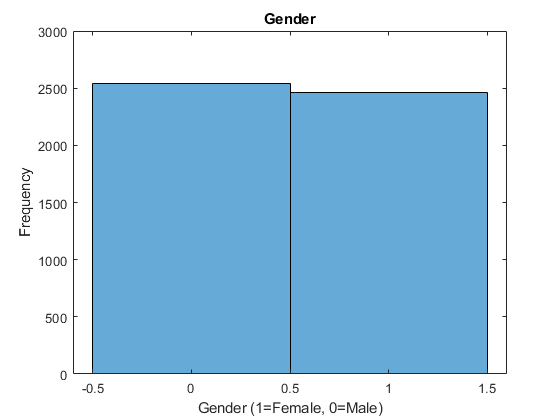

figure
histogram(Data_Needs.Gender)
title('Gender')
xlabel('Gender (1=Female, 0=Male)')
ylabel('Frequency')

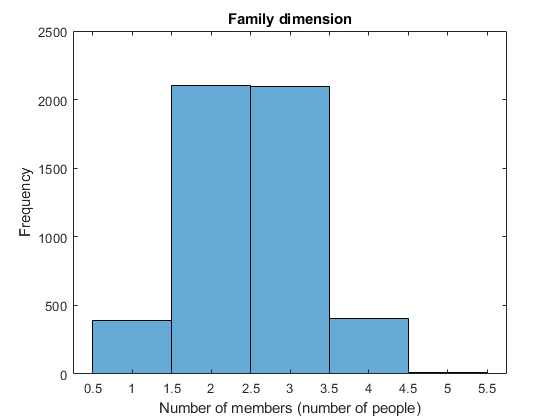

figure
histogram(Data_Needs.FamilyMembers)
title('Family dimension')
xlabel('Number of members (number of people)')
ylabel('Frequency')

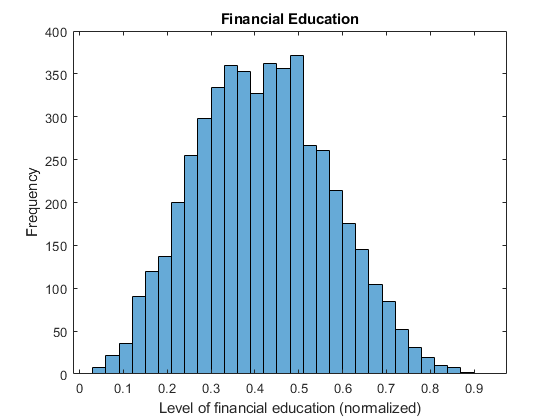

figure
histogram(Data_Needs.FinancialEducation)
title('Financial Education')
xlabel('Level of financial education (normalized)')
ylabel('Frequency')

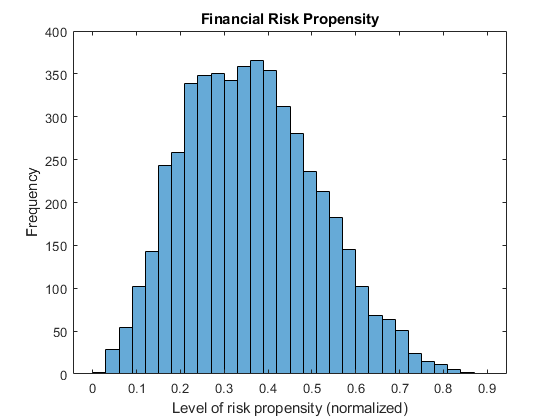

figure
histogram(Data_Needs.RiskPropensity)
title('Financial Risk Propensity')
xlabel('Level of risk propensity (normalized)')
ylabel('Frequency')

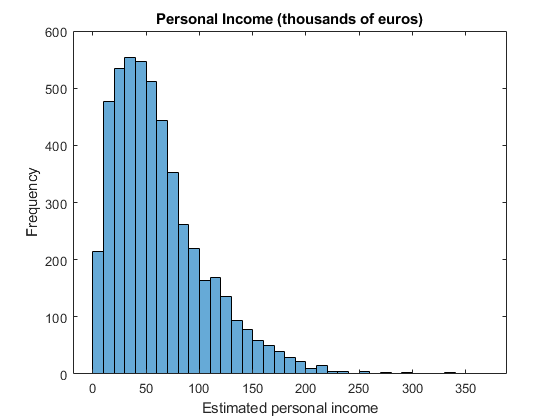


figure
histogram(Data_Needs.Income)
title('Personal Income (thousands of euros)')
xlabel('Estimated personal income')
ylabel('Frequency')

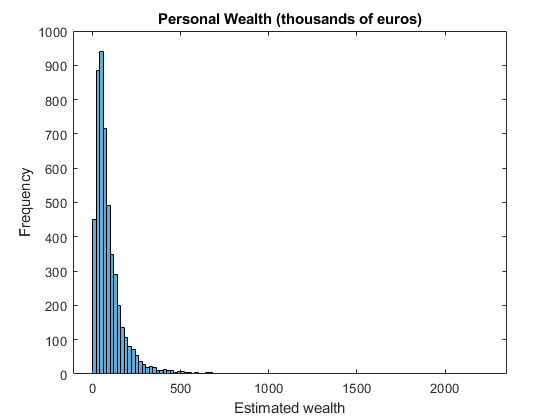

figure
histogram((Data_Needs.Wealth))
title('Personal Wealth (thousands of euros)')
xlabel('Estimated wealth')
ylabel('Frequency')

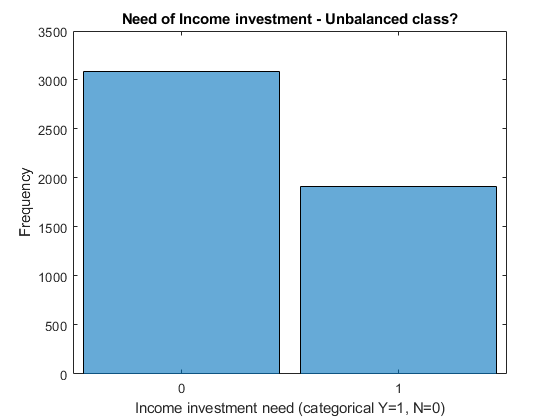

figure
histogram(Data_Needs.IncomeInvestment)
title('Need of Income investment - Unbalanced class?')
xlabel('Income investment need (categorical Y=1, N=0)')
ylabel('Frequency')

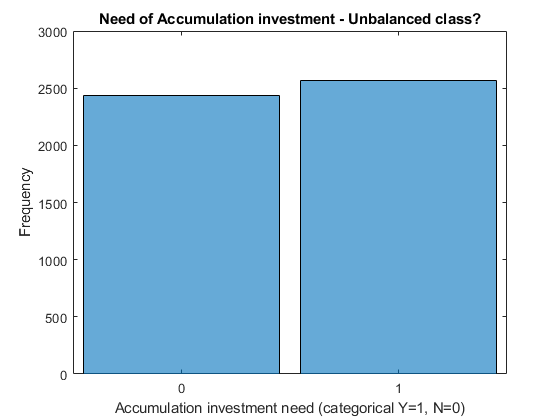

figure
histogram(Data_Needs.AccumulationInvestment)
title('Need of Accumulation investment - Unbalanced class?')
xlabel('Accumulation investment need (categorical Y=1, N=0)')
ylabel('Frequency')

### Data transformation

We apply transformation to Income and Wealth of dataset Data_Needs, in particular we compare the power and the log transformation and we choose the best one.

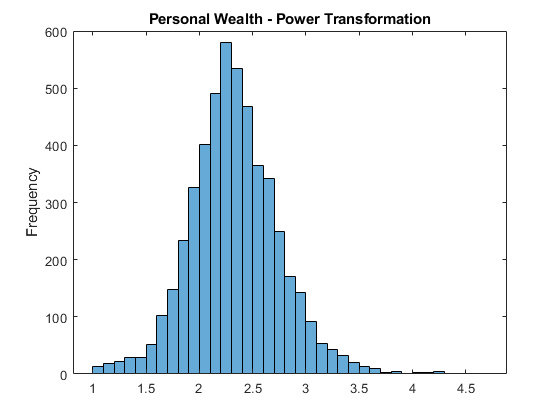

% We try power transformation to Wealth
p = 0.2; 
histogram(Data_Needs.Wealth.^p);        
title('Personal Wealth - Power Transformation')
ylabel('Frequency')

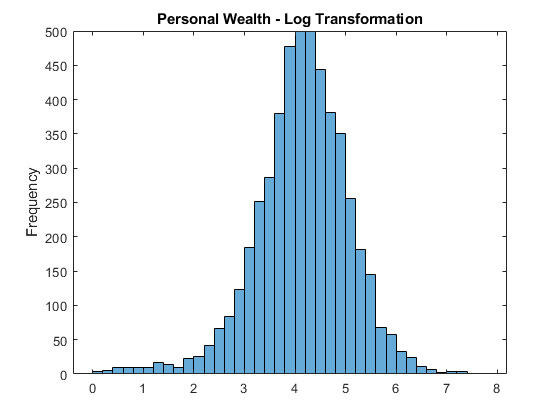

% We try log transformation for Wealth
histogram(log(Data_Needs.Wealth))      
title('Personal Wealth - Log Transformation')
ylabel('Frequency')

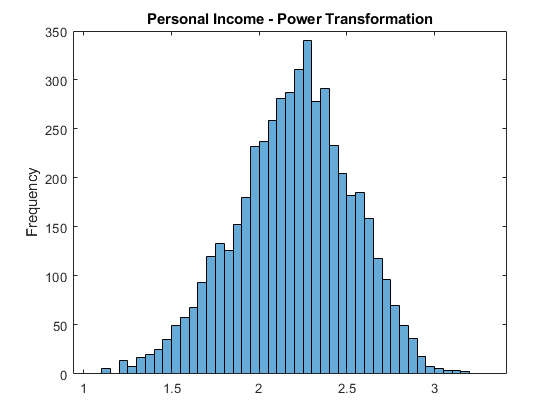

% We choose log-transformation for Wealth
logWealth = log(Data_Needs.Wealth); 

% We try power transformation for Income
histogram(Data_Needs.Income.^p); 
title('Personal Income - Power Transformation')
ylabel('Frequency')

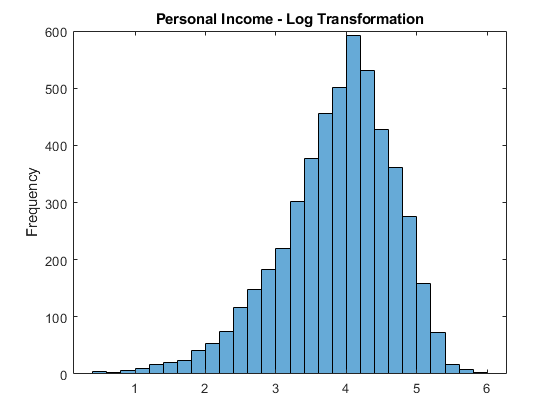

% We try log transformation for Income
histogram(log(Data_Needs.Income)) 
title('Personal Income - Log Transformation')
ylabel('Frequency')

% we choose log transformation for Income
logIncome = log(Data_Needs.Income); 

### Dimensionality Reduction

We try PCA for dimensionality reduction.

newData=Data_Needs(:,2:end-2);       % Exclude 1st col = ID and coloumns InvInc & InvAcc

% Numerical variables
N = vartype('numeric');
NumFeatures = newData(:,N);             % Subtable of numerical features
XNum = NumFeatures.Variables; 
XNum = rescale(XNum);                   % Normalize in [0, 1]

% Categorical variables
C7 = vartype('categorical');
CatFeatures = newData(:,C7);            % Subtable of categorical features

% Encoding (i.e. create dummy variables)
XCat = [];
for i = 1:size(CatFeatures, 2)
    XCat_i = dummyvar(grp2idx(CatFeatures{:,i}));
    XCat = [XCat XCat_i(:,1:end-1)];    % To use the dummy variables in a model, we must delete a column
end

X = [XCat XNum];                        % Rescaled Dataset

nSubSample = 5000;
rng('default')                          % for reproducibility
randRows = randperm(size(X, 1), nSubSample);
X = X(randRows', :);
newData=newData(randRows', :);

[coeff,score,latent] = pca(X(:,2:end));         % Explained variance = latent/sum(latent)*100
latent/sum(latent)*100                          % This is the variance explained by the pc's.

ans =    91.0323
    8.9612
    0.0043
    0.0019
    0.0003
    0.0001


As we can see, the first 2 components explain the majority of the variance. However there is a problem: there is no visible pattern or clustering. So we try other dimensionality reduction techniques.

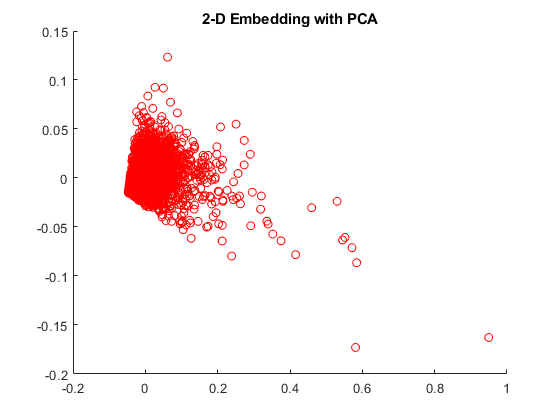

figure
scatter(score(:,1),score(:,2), 'r')
title('2-D Embedding with PCA')

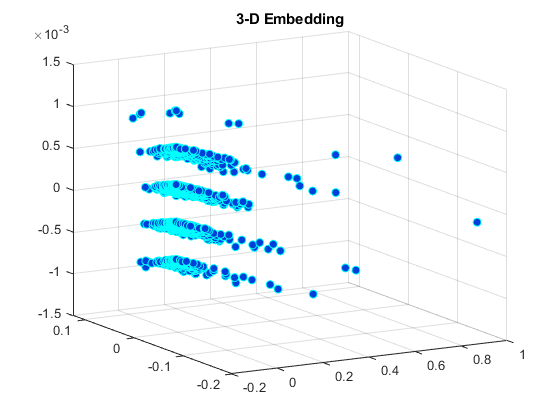

figure
scatter3(score(:,1),score(:,2),score(:,3),...
        'MarkerEdgeColor','c',...
        'MarkerFaceColor',[0 .25 .85])
title('3-D Embedding')
view(-30,15)

rng('default')          % for fair comparison

X is the rescaled dataset

X_Needs =[rescale(Data_Needs.Age) Data_Needs.Gender rescale(Data_Needs.FamilyMembers) rescale(Data_Needs.FinancialEducation)...
    rescale(Data_Needs.RiskPropensity) rescale(logIncome) rescale(logWealth)];

### **Multivariate perspective**

Matrix of scatter plots comparing our Xs by using our Ys (i.e. investment propensities) as grouping variable: it is relatively easy to visualize whether each group forms clusters/structures in the scatterplot.

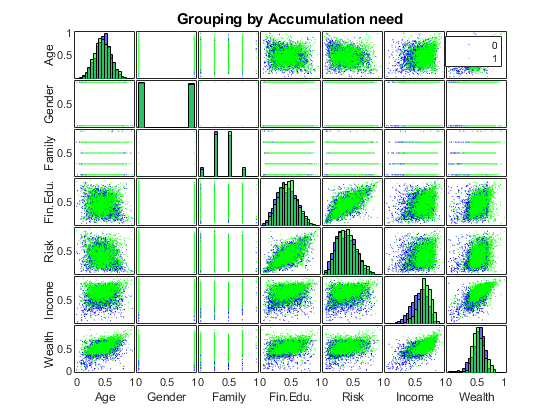

figure
xnames = {'Age','Gender', 'Family', 'Fin.Edu.', 'Risk', 'Income', 'Wealth'};
gplotmatrix(X_Needs,[],Data_Needs.AccumulationInvestment, [],[],[],[],'grpbars', xnames)
title('Grouping by Accumulation need')

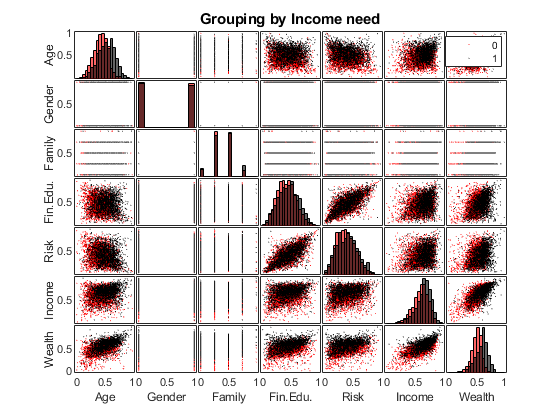

figure
xnames = {'Age','Gender', 'Family', 'Fin.Edu.', 'Risk', 'Income', 'Wealth'};
gplotmatrix(X_Needs,[],Data_Needs.IncomeInvestment, ["r", "k"],[],[],[],'grpbars', xnames)
title('Grouping by Income need')

Age and wealth seem to be a "good" separating feature for income investments.

### Dividing our data

Now we prepare training & test set for the training of the classification/regression algorithm.

nObs = size(Data_Needs, 1);
% First we compute the ratio between Wealth and Income for those individuals who have Wealth > 10
IncomeWealthRatio = zeros(nObs,1);
IncomeWealthRatio(Data_Needs.Wealth>10) = log(Data_Needs.Income(Data_Needs.Wealth>10))./log(Data_Needs.Wealth(Data_Needs.Wealth>10));
% Second we create a new variable which compare the rescaled wealth with the age
NewVariable = zeros(nObs,1);
NewVariable = (rescale(logWealth).*Data_Needs.Age);
% We introduced these variables to better distinguish the 2 different groups. 
% The last one should be a good variable for this analysis because we think that only wealthy
% and aged people should be intersted in this kind of product.

% We split the set: 0.75 is training set and 0.25 is test set
nObsTrain = round(0.75*nObs);

% Training output for the Income investment
yInvIncTrain = Data_Needs.IncomeInvestment(1:nObsTrain);
yInvIncTest = Data_Needs.IncomeInvestment(nObsTrain+1:end);

% Training output for the Accumulation Investment
yInvAccTrain = Data_Needs.AccumulationInvestment(1:nObsTrain);
yInvAccTest = Data_Needs.AccumulationInvestment(nObsTrain+1:end);

% Training and test input for both investment strategies
xnames = {'Wealth*Age', 'RiskPropensity','Age', 'Financial Education', 'Income', 'Wealth', 'ratio'};
Xsmall = [NewVariable rescale(Data_Needs.RiskPropensity) Data_Needs.Age rescale(Data_Needs.FinancialEducation) rescale(logIncome) rescale(logWealth) (IncomeWealthRatio)];
XsmallTrain = Xsmall(1:nObsTrain,:);
XsmallTest = Xsmall(nObsTrain+1:end,:);

% Regression training/test set need also risk coloumn
XsmallTestTableRegression = table(XsmallTest(:,1), XsmallTest(:,2), XsmallTest(:,3), XsmallTest(:,4), XsmallTest(:,5), XsmallTest(:,6), XsmallTest(:,7), 'VariableNames',xnames);
XsmallTrainTableRegression = table(XsmallTrain(:,1), XsmallTrain(:,2), XsmallTrain(:,3), XsmallTrain(:,4), XsmallTrain(:,5), XsmallTrain(:,6), XsmallTrain(:,7), 'VariableNames',xnames);
XsmallTrainTableClassification = table(XsmallTrain(:,1), XsmallTrain(:,3), XsmallTrain(:,4), XsmallTrain(:,5), XsmallTrain(:,6), XsmallTrain(:,7), 'VariableNames',xnames([1 3 4 5 6 7]));
XsmallTestTableClassification = table(XsmallTest(:,1), XsmallTest(:,3), XsmallTest(:,4), XsmallTest(:,5), XsmallTest(:,6), XsmallTest(:,7), 'VariableNames',xnames([1 3 4 5 6 7]));

### **Using the Regression Learner**

Now we use the regression learner to find the best model to retrieve the Risk Propensity from the other features. 

[trainedRegressor,validationAccuracy_reg] = trainRegressionModel(XsmallTrainTableRegression)

trainedRegressor = struct with fields:
           predictFcn: @(x)linearModelPredictFcn(predictorExtractionFcn(x))
    RequiredVariables: {'Age'  'Financial Education'  'Income'  'Wealth'  'Wealth*Age'  'ratio'}
          LinearModel: [1×1 LinearModel]
                About: 'This struct is a trained model exported from Regression Learner R2021a.'
         HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model.'


validationAccuracy_reg = 0.1225

The regressor is an optimizable ensemble. The results are not so good in terms of R2, indeed it is 0.5 un the training set and 0.48 on the test set.

### Using the classification learner

We built a classification algorithm for accumulation and another one for income

% Model for Income estimation
[trainedClassifierInc,validationAccuracy_Inc] = trainClassifierInc(XsmallTrainTableClassification, yInvIncTrain)

trainedClassifierInc = struct with fields:
                predictFcn: @(x)ensemblePredictFcn(predictorExtractionFcn(x))
         RequiredVariables: {'Age'  'Financial Education'  'Income'  'Wealth'  'Wealth*Age'  'ratio'}
    ClassificationEnsemble: [1×1 classreg.learning.classif.ClassificationEnsemble]
                     About: 'This struct is a trained model exported from Classification Learner R2021a.'
              HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model.'


validationAccuracy_Inc = 0.7962

% Model for Accumulation estimation
[trainedClassifierAcc,validationAccuracy_Acc] = trainClassifierAcc(XsmallTrainTableClassification, yInvAccTrain)

trainedClassifierAcc = struct with fields:
                predictFcn: @(x)ensemblePredictFcn(predictorExtractionFcn(x))
         RequiredVariables: {'Age'  'Financial Education'  'Income'  'Wealth'  'Wealth*Age'  'ratio'}
    ClassificationEnsemble: [1×1 classreg.learning.classif.ClassificationBaggedEnsemble]
                     About: 'This struct is a trained model exported from Classification Learner R2021a.'
              HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model.'


validationAccuracy_Acc = 0.8221

We use the optimized ensemble for this Classifier.

### Testing the classifiers

Notice that the classification is carried out without "risk propensity" of the clients because we will just have an estimate for this feature in the new dataset.

### Results "Accumulation classifier"

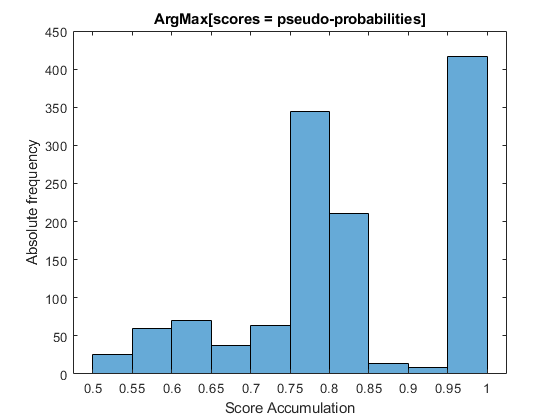

[labels_Acc,scores_Acc] = trainedClassifierAcc.predictFcn(XsmallTestTableClassification);
figure
histogram(max(scores_Acc')')
title('ArgMax[scores = pseudo-probabilities]')
xlabel('Score Accumulation')
ylabel('Absolute frequency')

tp_Acc = sum((labels_Acc == '1') & (yInvAccTest=='1'));             % True positive
fp_Acc = sum((labels_Acc == '1') & (yInvAccTest=='0'));             % False positive
fn_Acc = sum((labels_Acc == '0') & (yInvAccTest=='1'));             % False negative
tn_Acc = sum((labels_Acc == '0') & (yInvAccTest=='0'));             % True negative
prec_Acc = tp_Acc / (tp_Acc + fp_Acc)                               % Precision

prec_Acc = 0.8977

rec_Acc = tp_Acc / (tp_Acc + fn_Acc)                                % Recall

rec_Acc = 0.7669

F1_Acc = 2 * prec_Acc * rec_Acc / (prec_Acc + rec_Acc)              % F1 score

F1_Acc = 0.8271

acc_Acc = (tp_Acc + tn_Acc)/(tp_Acc + fp_Acc + fn_Acc + tn_Acc)     % Accuracy

acc_Acc = 0.8328

### **Results "Income classifier"**

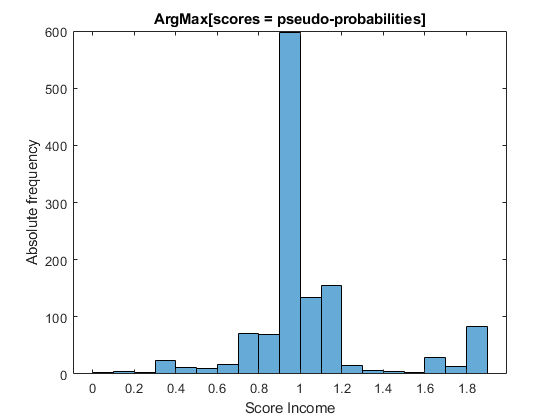

[labels_Inc,scores_Inc] = trainedClassifierInc.predictFcn(XsmallTestTableClassification);
figure
histogram(max(scores_Inc')')
title('ArgMax[scores = pseudo-probabilities]')
xlabel('Score Income')
ylabel('Absolute frequency')

tp_Inc = sum((labels_Inc == '1') & (yInvIncTest=='1'));             % True positive
fp_Inc = sum((labels_Inc == '1') & (yInvIncTest=='0'));             % False positive
fn_Inc = sum((labels_Inc == '0') & (yInvIncTest=='1'));             % False negative
tn_Inc = sum((labels_Inc == '0') & (yInvIncTest=='0'));             % True negative
prec_Inc = tp_Inc / (tp_Inc + fp_Inc)                               % Precision

prec_Inc = 0.9119

rec_Inc = tp_Inc / (tp_Inc + fn_Inc)                                % Recall

rec_Inc = 0.6135

F1_Inc = 2 * prec_Inc * rec_Inc / (prec_Inc + rec_Inc)              % F1 Score

F1_Inc = 0.7335

acc_Inc = (tp_Inc + tn_Inc)/(tp_Inc + fp_Inc + fn_Inc + tn_Inc)     % Accuracy

acc_Inc = 0.8256

### **IDEA:**

Now we move to the BankClients' dataset. We will use the classificator to assign the right investememt class to the clients. 

Then we will use as "advisor" the predicted risk (because it has just 0.52 Rsquared on test set)  to infer about the right product for each client/cluster of clients.

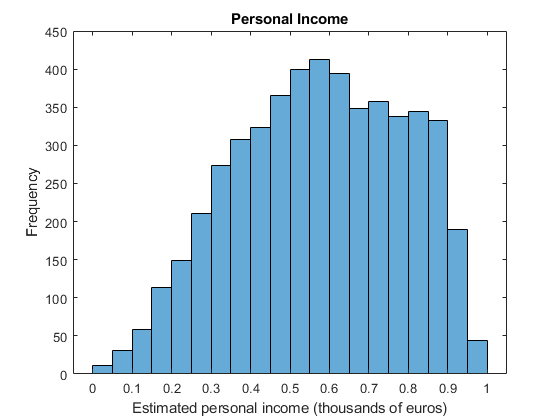

% Coloumns needed for Regressor
v=[2 8 9 11];               
Data_BankClients = BankClients(:,v);

figure
histogram(Data_BankClients.Income)
title('Personal Income')
xlabel('Estimated personal income (thousands of euros)')
ylabel('Frequency')

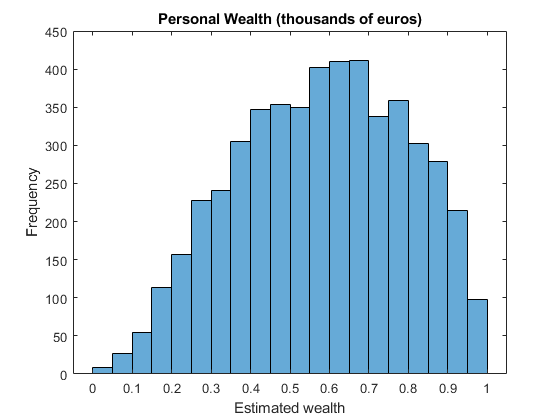

figure
histogram((Data_BankClients.Wealth))
title('Personal Wealth (thousands of euros)')
xlabel('Estimated wealth')
ylabel('Frequency')

### Regression

We run the regressor on the Dataset BankClients (we'll use only this features  {'Wealth*Age', 'Risk', 'Age', 'FinEdu', 'Income', 'Wealth'}) in order to add the "predicted_risk". 

Newratio = zeros(1,nObs)';
Newratio(Data_BankClients.Wealth>0.02) = Data_BankClients.Income(Data_BankClients.Wealth>0.02)./Data_BankClients.Wealth(Data_BankClients.Wealth>0.02);
X = table(Data_BankClients.Wealth.*(Data_BankClients.Age(:)), (Data_BankClients.Age), Data_BankClients.FinEdu, Data_BankClients.Income, Data_BankClients.Wealth, (Newratio),  'VariableNames', {'Wealth*Age', 'Age', 'Financial Education', 'Income', 'Wealth', 'ratio'});
% We use the table to predict the risks
predicted_risk = trainedRegressor.predictFcn(X);
min(predicted_risk)

ans = -0.5919

max(predicted_risk)

ans = 2.4765

length(predicted_risk(predicted_risk<0))

ans = 7

length(predicted_risk(predicted_risk>1))

ans = 7

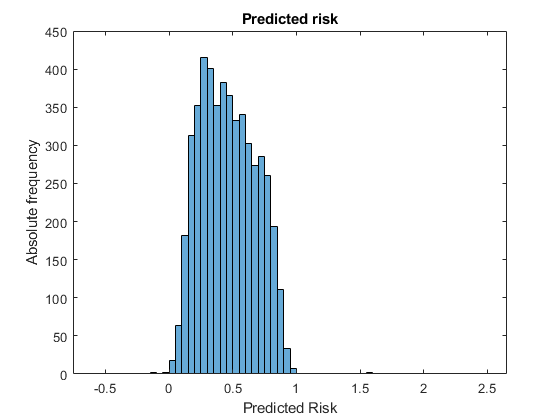

% We plot the predicted risks
figure
histogram(predicted_risk)
title('Predicted risk')
xlabel('Predicted Risk')
ylabel('Absolute frequency')

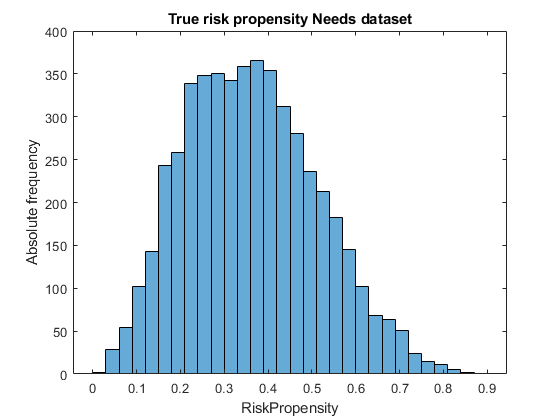

figure
histogram(Needs.RiskPropensity)
title('True risk propensity Needs dataset')
xlabel('RiskPropensity')
ylabel('Absolute frequency')

% We want a predicted risk between 0 and 1
predicted_risk(predicted_risk<0) = 0;
predicted_risk(predicted_risk>1) = 1;

### **Classification**

We classify all the people of the BankClients' dataset to understand which investment they prefer. 

Needed variables: {'NewVariable',  'Age', 'Financial Education', 'Income', 'Wealth'}.

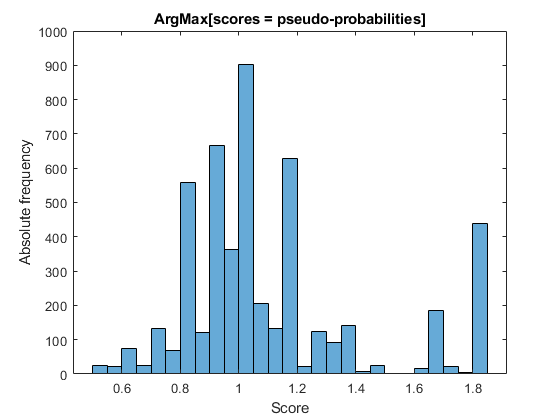

[labelsInc,scores] = trainedClassifierInc.predictFcn(X);
scores(scores(:,2)<0,2) = 1-scores(scores(:,2)<0,1);
scores(scores(:,1)<0,1) = 1-scores(scores(:,1)<0,2);
figure
histogram(max(scores')')
title('ArgMax[scores = pseudo-probabilities]')
xlabel('Score')
ylabel('Absolute frequency')

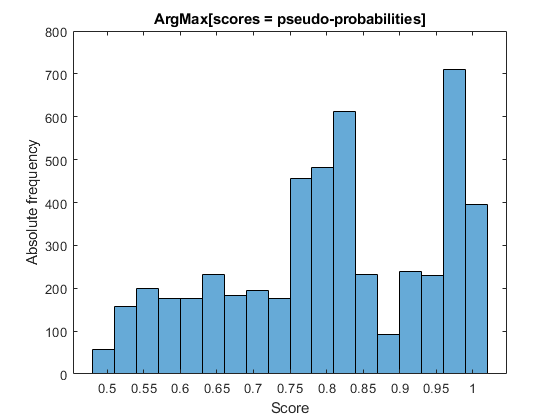

% Age of people who want an Income investment
(X.Age(labelsInc=='1'));
[labelsAcc, scores] = trainedClassifierAcc.predictFcn(X);
scores(scores(:,2)<0,2) = 1-scores(scores(:,2)<0,1);
scores(scores(:,1)<0,1) = 1-scores(scores(:,1)<0,2);
figure
histogram(max(scores')')
title('ArgMax[scores = pseudo-probabilities]')
xlabel('Score')
ylabel('Absolute frequency')

% Number of people who have an Accumulation Investment
length(labelsAcc(labelsAcc=='1'))

ans = 2640

Let's inspect these results

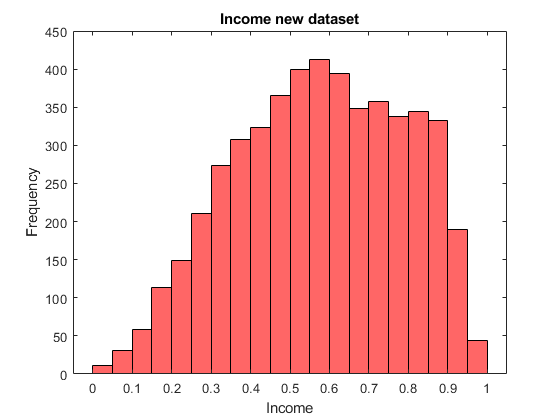

% Let's have a look at the new dataset
figure
histogram(BankClients.Income, 'FaceColor', 'r')
title('Income new dataset')
xlabel('Income')
ylabel('Frequency')

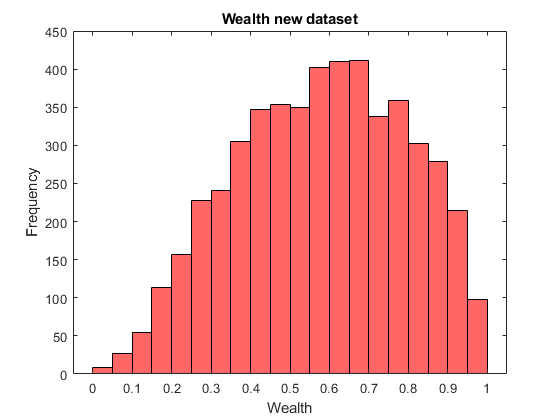

figure
histogram(BankClients.Wealth, 'FaceColor', 'r')
title('Wealth new dataset')
xlabel('Wealth')
ylabel('Frequency')

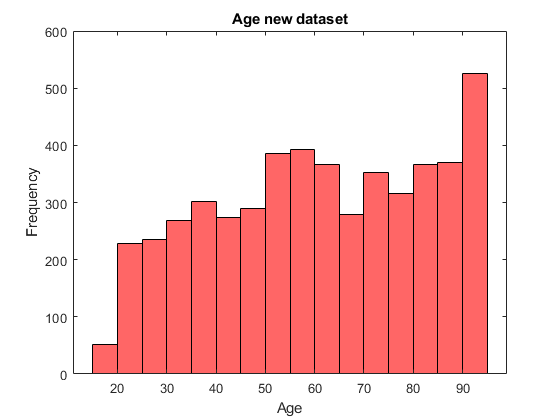

figure
histogram(BankClients.Age, 'FaceColor', 'r')
title('Age new dataset')
xlabel('Age')
ylabel('Frequency')

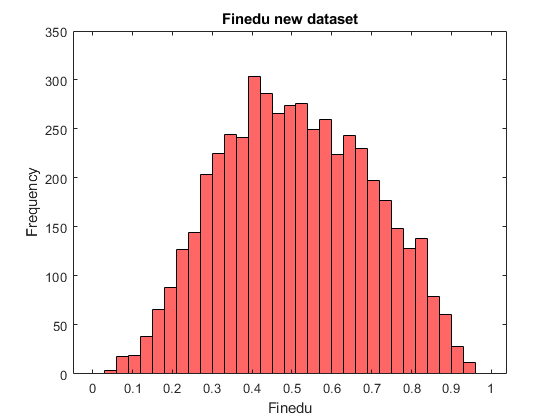

figure
histogram(BankClients.FinEdu, 'FaceColor', 'r')
title('Finedu new dataset')
xlabel('Finedu')
ylabel('Frequency')

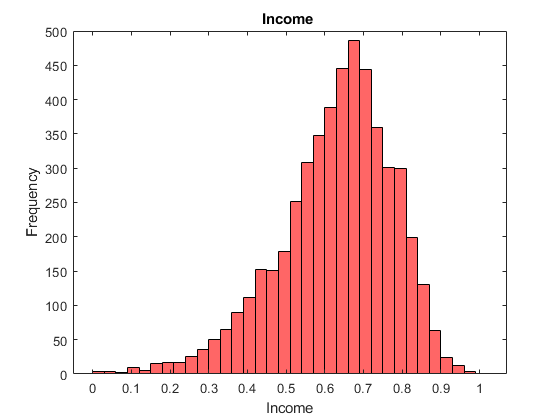


figure
histogram(rescale(log(Needs.Income)) , 'FaceColor', 'r')
title('Income ')
xlabel('Income')
ylabel('Frequency')

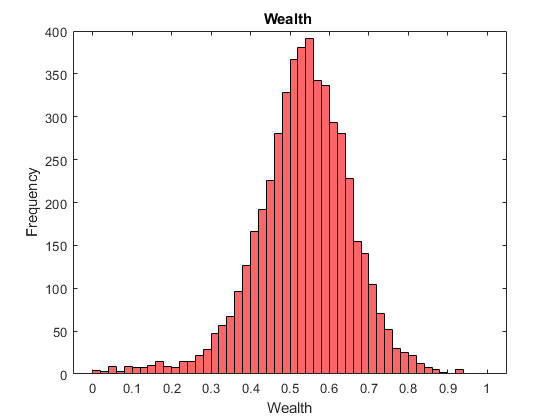

figure
histogram(rescale(log(Needs.Wealth)), 'FaceColor', 'r')
title('Wealth ')
xlabel('Wealth')
ylabel('Frequency')

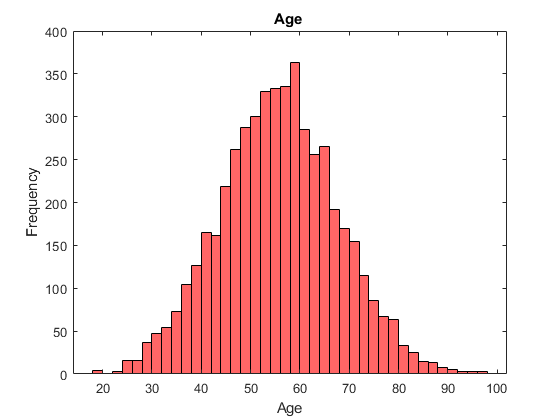

figure
histogram(Needs.Age, 'FaceColor', 'r')
title('Age ')
xlabel('Age')
ylabel('Frequency')

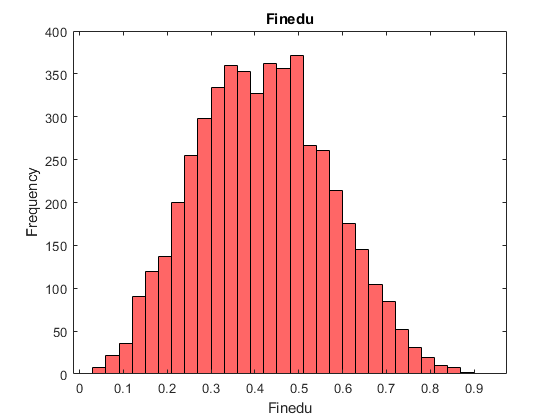


figure
histogram(Needs.FinancialEducation, 'FaceColor', 'r')
title('Finedu')
xlabel('Finedu')
ylabel('Frequency')

Here we can compare the two datasets and we can see there are some differences particularly in the age.

### **Client segmentation**

Now we segment clients of the dataset "BankClients". The Idea is to provide the right investment product to each client basing on his cluster and his estimated risk propensity/investment interest (Accumulation or Income) 

% Numerical
N = vartype('numeric');
Data_BankClients2 = BankClients(:,2:end);   % Exclude 1st col = ID
NumFeatures = Data_BankClients2(:,N);       % Subtable of numerical features
XNum = NumFeatures.Variables; 
XNum = rescale(XNum);                       % Normalize in [0, 1]

% Categorical
C7 = vartype('categorical');
CatFeatures = Data_BankClients2(:,C7);      % Subtable of categorical features

% Encoding (i.e. create dummy variables)
XCat = [];
for i = 1:size(CatFeatures, 2)
    XCat_i = dummyvar(grp2idx(CatFeatures{:,i}));
    XCat = [XCat XCat_i(:,1:end-1)];        % To use the dummy variables in a model, we must delete a column
end

X = [XCat XNum];

nSubSample = 1950;
rng('default')                              % for reproducibility
randRows = randperm(size(X, 1), nSubSample);
X = X(randRows', :);

% Data Exploration
[coeff,score,latent] = pca(X);              % Explained variance = latent/sum(latent)*100
latent/sum(latent)*100

ans =    20.3644
   16.1141
   15.5047
   13.8232
   12.5884
    6.2381
    4.9429
    3.6388
    2.4885
    2.3774


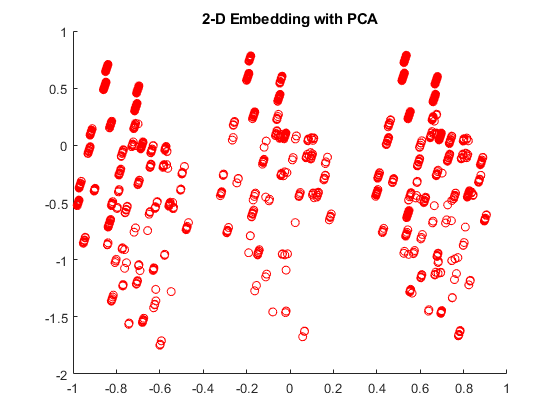

figure
scatter(score(:,1),score(:,2), 'r')
title('2-D Embedding with PCA')

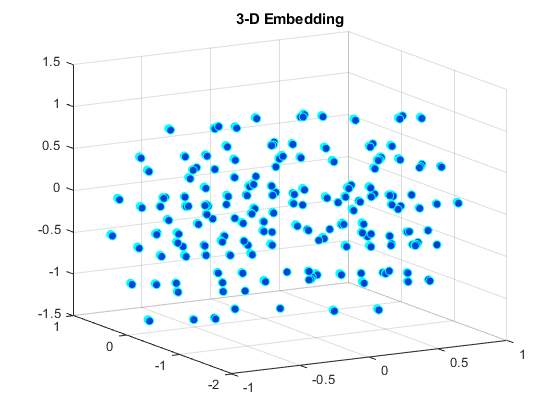

figure
scatter3(score(:,1),score(:,2),score(:,3),...
        'MarkerEdgeColor','c',...
        'MarkerFaceColor',[0 .25 .85])
title('3-D Embedding')
view(-30,15)

rng('default') % for fair comparison
Y = tsne(X,'Algorithm','exact','Distance', @MixDistance,'NumDimensions',3);

% We use 17 cluster k-medoids
[IDX17, C17, SUMD17, D17, MIDX17, INFO17] = kmedoids(X,17,'Distance', @MixDistance,'replicates',20);

Let's inspect the results we obtained.

ClusterCardinality = grpstats(X(:, 1),IDX17, 'numel');
ClusterCardinality = ClusterCardinality/sum(ClusterCardinality);
ClusterMean = 100*grpstats(X(:,1:end),IDX17, @mean);
nomicolonne = {'Femmine', 'Non occupato', 'Operaio', 'Dirigente', 'Impr/Libe prof', 'Nord', 'Centro', 'Picolo centro', 'Media', 'No investimenti', 'lump sum', 'Age', 'fam size', 'Income', 'Wealth', 'Debt', 'Finedu', 'ESG', 'Digital', 'BankFriend', 'Lifestyle', 'Luxury', 'Saving'};
ClusterMean =  array2table([ClusterMean ClusterCardinality], 'VariableNames',[nomicolonne {'Cardinality'}])

ClusterMean = 17×24 table
    Femmine    Non occupato    Operaio    Dirigente    Impr/Libe prof     Nord     Centro    Picolo centro    Media     No investimenti    lump sum     Age      fam size    Income     Wealth      Debt      Finedu       ESG      Digital    BankFriend    Lifestyle    Luxury     Saving     Cardinality
    _______    ____________    _______    _________    ______________    ______    ______    _____________    ______

Now we check how the people in the cluster are classified. In this way we understand how propose the Accumulation investment and the Income investment.

% First: we check the people who want an Accumulation investment
counter_Acc = zeros(1,17);
SmallLabAcc = labelsAcc(randRows);
for (i = 1:17)
    idx = SmallLabAcc(IDX17==i);
    counter_Acc(i) = length(idx(idx=="1"))/length(idx);
end
counter_Acc

counter_Acc =     0.5397    0.4872    0.8207    0.4748    0.3852    0.6197    0.7660    0.4154    0.4507    0.4531    0.6000    0.4365    0.4118    0.3273    0.5897    0.4481    0.4510


% Second: we check the people who want an Income investment
counter_Inc = zeros(1,17);
SmallLabInc = labelsInc(randRows);
for (i = 1:17)
    idx = SmallLabInc(IDX17==i);
    counter_Inc(i) = length(idx(idx=="1"))/length(idx);
end
counter_Inc

counter_Inc =     0.4048    0.3538    0.3103    0.3453    0.2593    0.3662    0.3351    0.3538    0.3944    0.2031    0.3385    0.2652    0.3333    0.3818    0.4872    0.2842    0.2549


Now we predict the risk for the selected people.

SmallPredRisk = predicted_risk(randRows);
%Third: we compute the average predicted risk for each cluster
counter_risk = zeros(1,17);
for (i = 1:17)
    idx = SmallPredRisk(IDX17==i);
    counter_risk(i) = sum(idx)/length(idx);
end
counter_risk

counter_risk =     0.4842    0.4157    0.6605    0.3938    0.3717    0.5161    0.6265    0.3920    0.4987    0.4195    0.4776    0.4238    0.3634    0.3573    0.3966    0.4041    0.4443


% Fourth: we check the people who want both the investments
counter_Accinc = zeros(1,17);
SmallLabInc = labelsInc(randRows);
SmallLabAcc = labelsAcc(randRows);
for (i = 1:17)
    idxInc = SmallLabInc(IDX17==i);
    idxAcc = SmallLabAcc(IDX17==i);
    counter_AccInc(i) = sum((idxInc=="1").*(idxAcc=="1"))/sum(IDX17==i);
end
counter_AccInc

counter_AccInc =     0.2817    0.2513    0.2552    0.2662    0.1852    0.2958    0.2606    0.2000    0.1831    0.1250    0.2615    0.1934    0.2549    0.2000    0.3846    0.1803    0.1569


% Fifth: we check the people who want an investment
counter_invest = zeros(1,17);
SmallLabInc = labelsInc(randRows);
SmallLabAcc = labelsAcc(randRows);
for (i = 1:17)
    idxInc = SmallLabInc(IDX17==i);
    idxAcc = SmallLabAcc(IDX17==i);
    counter_invest(i) = 1-sum((idxInc=="0").*(idxAcc=="0"))/sum(IDX17==i);
end
counter_invest

counter_invest =     0.6627    0.5897    0.8759    0.5540    0.4593    0.6901    0.8404    0.5692    0.6620    0.5312    0.6769    0.5083    0.4902    0.5091    0.6923    0.5519    0.5490


% Trial to see if the last results obtained are correct
counter_Acc + counter_Inc - counter_AccInc

ans =     0.6627    0.5897    0.8759    0.5540    0.4593    0.6901    0.8404    0.5692    0.6620    0.5312    0.6769    0.5083    0.4902    0.5091    0.6923    0.5519    0.5490


% Aggregating clusters
Educated_top_jobs_elite = zeros(1,4);%cluster 3 + 7
Educated_top_jobs_elite(1) = (counter_Acc(3)*ClusterCardinality(3)+counter_Acc(7)*ClusterCardinality(7))/(ClusterCardinality(3)+ClusterCardinality(7));
Educated_top_jobs_elite(2) = (counter_Inc(3)*ClusterCardinality(3)+counter_Inc(7)*ClusterCardinality(7))/(ClusterCardinality(3)+ClusterCardinality(7));
Educated_top_jobs_elite(3) = (counter_risk(3)*ClusterCardinality(3)+counter_risk(7)*ClusterCardinality(7))/(ClusterCardinality(3)+ClusterCardinality(7));
Educated_top_jobs_elite(4) = (counter_invest(3)*ClusterCardinality(3)+counter_invest(7)*ClusterCardinality(7))/(ClusterCardinality(3)+ClusterCardinality(7));
Educated_top_jobs_elite

Educated_top_jobs_elite =     0.7898    0.3243    0.6413    0.8559


Wage_pension_slaver = zeros(1,4);%cluster 2 + 8 + 15
Wage_pension_slaver(1) = (counter_Acc(2)*ClusterCardinality(2)+counter_Acc(8)*ClusterCardinality(8)+counter_Acc(15)*ClusterCardinality(15))/(ClusterCardinality(2)+ClusterCardinality(8)+ClusterCardinality(15));
Wage_pension_slaver(2) = (counter_Inc(2)*ClusterCardinality(2)+counter_Inc(8)*ClusterCardinality(8)+counter_Inc(15)*ClusterCardinality(15))/(ClusterCardinality(2)+ClusterCardinality(8)+ClusterCardinality(15));
Wage_pension_slaver(3) = (counter_risk(2)*ClusterCardinality(2)+counter_risk(8)*ClusterCardinality(8)+counter_risk(15)*ClusterCardinality(15))/(ClusterCardinality(2)+ClusterCardinality(8)+ClusterCardinality(15));
Wage_pension_slaver(4) = (counter_invest(2)*ClusterCardinality(2)+counter_invest(8)*ClusterCardinality(8)+counter_invest(15)*ClusterCardinality(15))/(ClusterCardinality(2)+ClusterCardinality(8)+ClusterCardinality(15));
Wage_pension_slaver

Wage_pension_slaver =     0.4849    0.3712    0.4080    0.5987


No_investing_appetite = zeros(1,4);%cluster 9 + 17 +5 +13 +16
No_investing_appetite(1) = (counter_Acc(9)*ClusterCardinality(9)+counter_Acc(17)*ClusterCardinality(17)+counter_Acc(5)*ClusterCardinality(5)+counter_Acc(13)*ClusterCardinality(13)+counter_Acc(16)*ClusterCardinality(16))/(ClusterCardinality(9)+ClusterCardinality(17)+ClusterCardinality(5)+ClusterCardinality(13)+ClusterCardinality(16));
No_investing_appetite(2) = (counter_Inc(9)*ClusterCardinality(9)+counter_Inc(17)*ClusterCardinality(17)+counter_Inc(5)*ClusterCardinality(5)+counter_Inc(13)*ClusterCardinality(13)+counter_Inc(16)*ClusterCardinality(16))/(ClusterCardinality(9)+ClusterCardinality(17)+ClusterCardinality(5)+ClusterCardinality(13)+ClusterCardinality(16));
No_investing_appetite(3) = (counter_risk(9)*ClusterCardinality(9)+counter_risk(17)*ClusterCardinality(17)+counter_risk(5)*ClusterCardinality(5)+counter_risk(13)*ClusterCardinality(13)+counter_risk(16)*ClusterCardinality(16))/(ClusterCardinality(9)+ClusterCardinality(17)+ClusterCardinality(5)+ClusterCardinality(13)+ClusterCardinality(16));
No_investing_appetite(4) = (counter_invest(9)*ClusterCardinality(9)+counter_invest(17)*ClusterCardinality(17)+counter_invest(5)*ClusterCardinality(5)+counter_invest(13)*ClusterCardinality(13)+counter_invest(16)*ClusterCardinality(16))/(ClusterCardinality(9)+ClusterCardinality(17)+ClusterCardinality(5)+ClusterCardinality(13)+ClusterCardinality(16));
No_investing_appetite

No_investing_appetite =     0.4277    0.2953    0.4088    0.5356



Retired_lump_sum_investor = zeros(1,4);%cluster 4 + 10 + 12 + 14
Retired_lump_sum_investor(1) = (counter_Acc(4)*ClusterCardinality(4)+counter_Acc(10)*ClusterCardinality(10)+counter_Acc(12)*ClusterCardinality(12)+counter_Acc(14)*ClusterCardinality(14))/(ClusterCardinality(4)+ClusterCardinality(10)+ClusterCardinality(12)+ClusterCardinality(14));
Retired_lump_sum_investor(2) = (counter_Inc(4)*ClusterCardinality(4)+counter_Inc(10)*ClusterCardinality(10)+counter_Inc(12)*ClusterCardinality(12)+counter_Inc(14)*ClusterCardinality(14))/(ClusterCardinality(4)+ClusterCardinality(10)+ClusterCardinality(12)+ClusterCardinality(14));
Retired_lump_sum_investor(3) = (counter_risk(4)*ClusterCardinality(4)+counter_risk(10)*ClusterCardinality(10)+counter_risk(12)*ClusterCardinality(12)+counter_risk(14)*ClusterCardinality(14))/(ClusterCardinality(4)+ClusterCardinality(10)+ClusterCardinality(12)+ClusterCardinality(14));
Retired_lump_sum_investor(4) = (counter_invest(4)*ClusterCardinality(4)+counter_invest(10)*ClusterCardinality(10)+counter_invest(12)*ClusterCardinality(12)+counter_invest(14)*ClusterCardinality(14))/(ClusterCardinality(4)+ClusterCardinality(10)+ClusterCardinality(12)+ClusterCardinality(14));
Retired_lump_sum_investor

Retired_lump_sum_investor =     0.4374    0.2961    0.4053    0.5262


Well_off = zeros(1,4);%cluster 1 + 6 + 11
Well_off(1) = (counter_Acc(1)*ClusterCardinality(1)+counter_Acc(6)*ClusterCardinality(6)+counter_Acc(11)*ClusterCardinality(11))/(ClusterCardinality(1)+ClusterCardinality(6)+ ClusterCardinality(11));
Well_off(2) = (counter_Inc(1)*ClusterCardinality(1)+counter_Inc(6)*ClusterCardinality(6)+ counter_Inc(11)*ClusterCardinality(11) )/(ClusterCardinality(1)+ClusterCardinality(6)+ ClusterCardinality(11));
Well_off(3) = (counter_risk(1)*ClusterCardinality(1)+counter_risk(6)*ClusterCardinality(6)+ counter_risk(11)*ClusterCardinality(11))/(ClusterCardinality(1)+ClusterCardinality(6)+ ClusterCardinality(11));
Well_off(4) = (counter_invest(1)*ClusterCardinality(1)+counter_invest(6)*ClusterCardinality(6)+ counter_invest(11)*ClusterCardinality(11))/(ClusterCardinality(1)+ClusterCardinality(6)+ ClusterCardinality(11));
Well_off

Well_off =     0.5644    0.3866    0.4889    0.6701


Pay attention: if the result are not coherent with the ones obtained in the Power Point presentation, please run again the code because sometimes the algorithm gives different numbers to the clusters previously found.

colnames = {'predicted Accumulation', 'predicted Income', 'predicted Risk', '%Investing in at least 1 product'};
rownames = {'Educated top jobs elite', 'Wage pension slaver', 'No investing appetite person', 'Retired lump sum investor', 'Well-off nearly retired'};
Final_clusters_table = array2table([Educated_top_jobs_elite; Wage_pension_slaver; No_investing_appetite; Retired_lump_sum_investor; Well_off], 'VariableNames', colnames, 'RowNames',rownames)

Final_clusters_table = 5×4 table
                                    predicted Accumulation    predicted Income    predicted Risk    %Investing in at least 1 product
                                    ______________________    ________________    ______________    ________________________________

    Educated top jobs elite                0.78979                0.32432             0.6413                    0.85586             
    Wage pension slaver                    0.48495                0.37124            0.40803                    0.59866             
    No investing appetite person            0.4277                0.29532            0.40883                    0.53564             
    Retired lump sum investor              0.43736                0.29613            0.40535     

new_clusters=zeros(1,1950);
for (i=1:1950)
    if (IDX17(i)==3 || IDX17(i)==7 ) 
        new_clusters(i)=1;%'Educated_top_jobs_elite';
    end
    if (IDX17(i)==2 || IDX17(i)==8 || IDX17(i)==15 ) 
        new_clusters(i)=2;%'Wage_pension_slaver';
    end
    if (IDX17(i)==9 || IDX17(i)==17 || IDX17(i)==5 || IDX17(i)==13 || IDX17(i)==16) 
        new_clusters(i)=3;%'No_investing_appetite';
    end
    if (IDX17(i)==4 || IDX17(i)==10 || IDX17(i)==12 || IDX17(i)==14) 
        new_clusters(i)=4;%'Retired_lump_sum_investor';
    end
    if (IDX17(i)==1 || IDX17(i)==6 || IDX17(i)==11) 
        new_clusters(i)=5;%'Well_off';
    end
end
cluster_names={'Educated top jobs elite', 'Wage pension slaver', 'No investing appetite', 'Retired lump sum investor', 'Well off'};


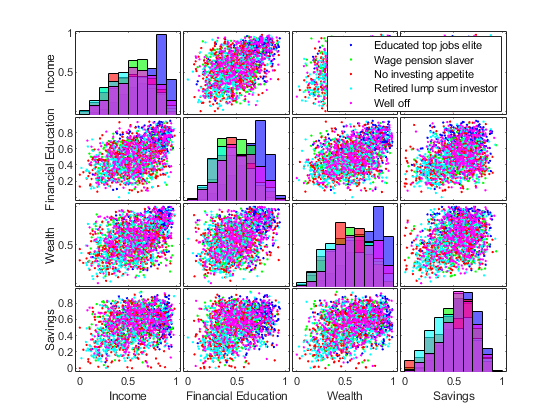

Data4Plot = [BankClients.Income(randRows)  BankClients.FinEdu(randRows)  BankClients.Wealth(randRows)  BankClients.Saving(randRows)];
xnames = {'Income', 'Financial Education', 'Wealth', 'Savings'};
gplotmatrix(Data4Plot(1:1950,:),[],new_clusters,[],[],[5],[],'grpbars', xnames)
h= findobj('Tag','legend');
set(h(1), 'String', cluster_names, 'FontSize', 8);

Finally we plot the obtained results.

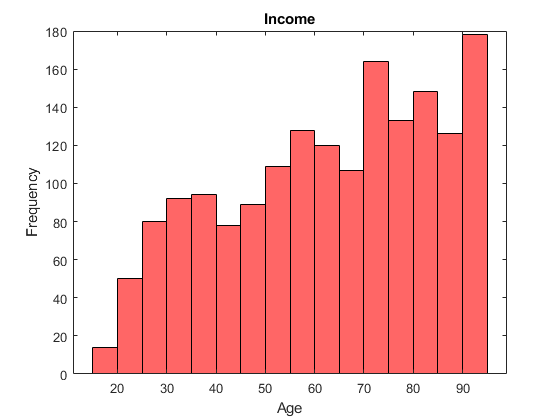

figure
histogram(Data_BankClients2.Age(labelsInc=='1'), 'FaceColor', 'r')
title('Income')
xlabel('Age')
ylabel('Frequency')

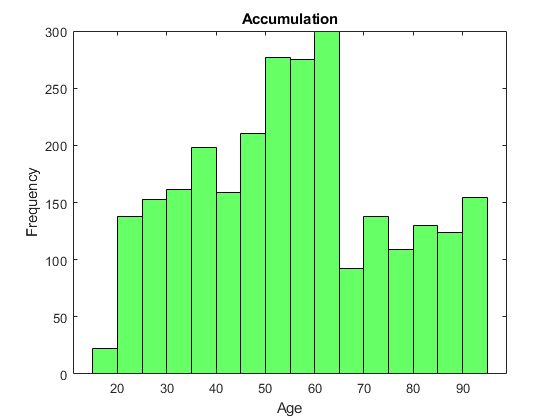

figure
histogram(Data_BankClients2.Age(labelsAcc=='1'), 'FaceColor', 'g')
title('Accumulation')
xlabel('Age')
ylabel('Frequency')%come ci aspettiamo

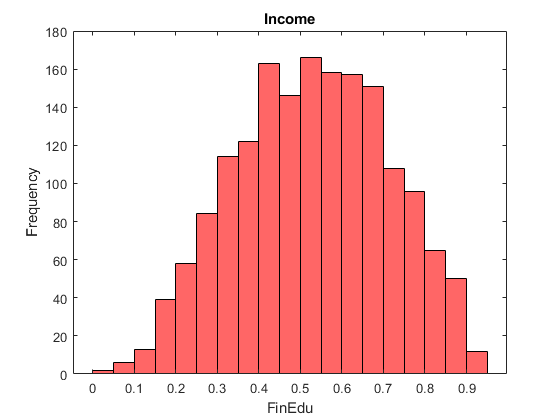

figure
histogram(Data_BankClients2.FinEdu(labelsInc=='1'), 'FaceColor', 'r')
title('Income')
xlabel('FinEdu')
ylabel('Frequency')

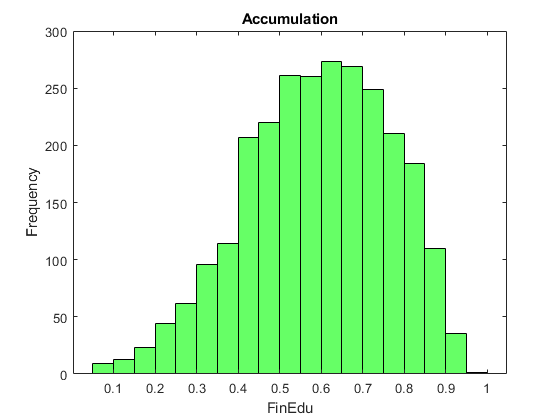

figure
histogram(Data_BankClients2.FinEdu(labelsAcc=='1'), 'FaceColor', 'g')
title('Accumulation')
xlabel('FinEdu')
ylabel('Frequency')

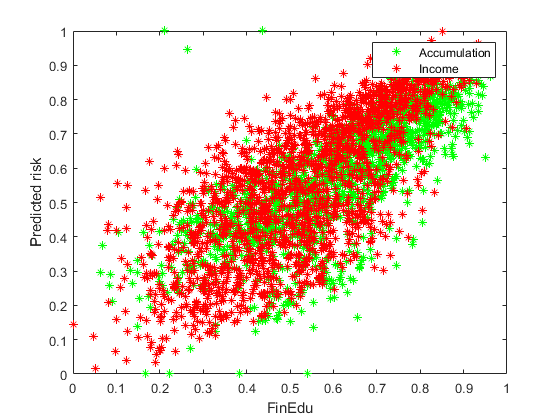

figure
plot(Data_BankClients2.FinEdu(labelsAcc=='1'), predicted_risk(labelsAcc=='1'), '*g')
hold on
plot(Data_BankClients2.FinEdu(labelsInc=='1'), predicted_risk(labelsInc=='1'), '*r')
legend('Accumulation', 'Income')
xlabel('FinEdu')
ylabel('Predicted risk')